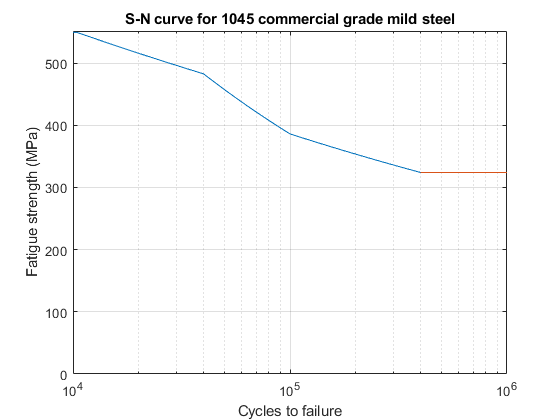

% ##############################
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Calculate damage number from acceleration 
% and strain data and compare them.
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Author: HC Janse van Vuuren
% Date: 11/10/2022
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% ##############################

clear

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%% # Beam and material properties
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% Beam Parameters
Length = 1.6;       % Beam lenth (m)
width = 40/1000;    % Beam width (m)
th = 4.5/1000;      % Beam thickness (m)
A = width*th;       % Beam cross sectional area (m^3)
I = width*(th^3)/12;% Beam moment of inertia about the z-axis (m^4)
rho = 7800;         % Beam mild steel density (kg/m^3)
E = 200*10^9;       % Beam mild steel Young's modulus (Pa)
m = A*Length*rho;   % Beam mass (kg)

% S-N curve for commercial grade mild steel
% 1045 Plain carbon (mild) steel HR,N - SN curve (Shigley)

S = [80 70 56 47 47 47 47].*6894.757./1000;     % Stress range to failure (MPa)
N = [1e4 4e4 1e5 4e5 1e6 4e6 1e7];      % Cycles to failure

ST = 107.*6894.757./1000;   % Tensile strength (MPa)
SY = 63.*6894.757./1000;    % Yield strength (MPa)

b1 = ( log(S(1)/S(2)) / log(N(1)/N(2)) );   % SN curve exponent constant b
b2 = ( log(S(2)/S(3)) / log(N(2)/N(3)) );   % SN curve exponent constant b
b3 = ( log(S(3)/S(4)) / log(N(3)/N(4)) );   % SN curve exponent constant b
a1 = S(1)/(N(1)^b1);   % SN curve scaling constant a
a2 = S(2)/(N(2)^b2);   % SN curve scaling constant a
a3 = S(3)/(N(3)^b3);   % SN curve scaling constant a
a4 = S(end);           % SN curve scaling constant a

% S1 = @(n) a1*n^b1;    % S-N curve (MPa-Cycles) for 1e4 < n <= 4e4
% S2 = @(n) a2*n^b2;    % S-N curve (MPa-Cycles) for 4e4 < n <= 1e5
% S3 = @(n) a3*n^b3;    % S-N curve (MPa-Cycles) for 1e5 < n <= 4e5
% S4 = @(n) n/n + a4;   % S-N curve (MPa-Cycles) for 4e5 < n

N1 = @(s) (s/a1)^(1/b1);    % N-S curve (Cycles-MPa) for 551.58056 > s >= 482.63299
N2 = @(s) (s/a2)^(1/b2);    % N-S curve (Cycles-MPa) for 482.63299	> s >= 386.106392
N3 = @(s) (s/a3)^(1/b3);    % N-S curve (Cycles-MPa) for 386.106392 > s >= 324.053579
N4 = @(s) s-s + inf;        % N-S curve (Cycles-MPa) for 324.053579 > s

% Generate SN curve values
s = linspace(S(4),S(1));    % SN curve stress range
n = zeros(length(s),1);     % SN curve cycle range

for i = 1:length(n)
    if S(1) <= s(i)
        n(i) = 1;
    elseif S(1) > s(i) && s(i) >= S(2)
        n(i) = N1(s(i));
    elseif S(2) > s(i) && s(i) >= S(3)
        n(i) = N2(s(i));
    elseif S(3) > s(i) && s(i) >= S(4)
        n(i) = N3(s(i));
    elseif S(4) > s(i)
        n(i) = inf;
    end
end

% Plot SN curve
semilogx(n,s, N(4:end),S(4:end))
grid on
ylim([0 S(1)])
xlim([1e4 1e6])
title('S-N curve for 1045 commercial grade mild steel')
xlabel('Cycles to failure')
ylabel('Fatigue strength (MPa)')

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%% # Sensor data import
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

Run18T = importdata('Run 18 Throughput.mat');% Import all measurement data of run

dt = Run18T.Signal_0.x_values.increment;     % Sampling period - Length of each time step (s)
fs =  1/dt;                                  % Sampling frequency (Hz)
tend = Run18T.Signal_0.x_values.start_value + (Run18T.Signal_0.x_values.number_of_values-1) * dt;
t = Run18T.Signal_0.x_values.start_value : dt : (tend); % Time range
entries = length(t);                                    % Data array length

acc = Run18T.Signal_2.y_values.values(1:entries,:);     % Whole acceleration data set (m/s^2)
strainData = Run18T.Signal_0.y_values.values;     % Whole strain data set (m/m)
stress = strainData.*E;     % Whole strain data set (m/s^2)

measPointsA = min(size(Run18T.Signal_2.y_values.values));     %number of acceleration measuring points
measPointsS = min(size(Run18T.Signal_0.y_values.values));     %number of strain measuring points

x = linspace(0,Length,measPointsA);     % Position range along the x-axis (beam length) (m)
dx = x(2) - x(1);                       % Distance between measutring points (m)

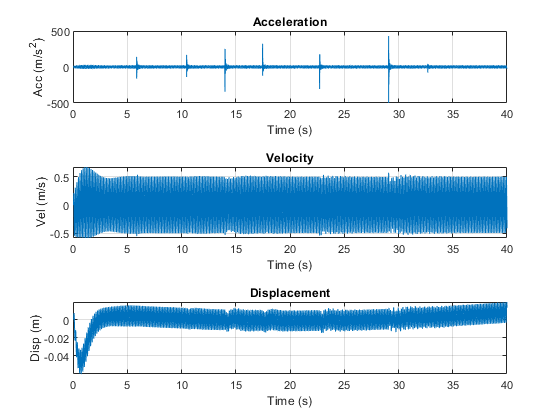

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Acc to disp (integrate in time)
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% Declare variables
accD = zeros(size(acc));    % Detrended acceleration (m/s^2)
acc2 = zeros(size(acc));    % Filtered acceleration (m/s^2)
vel = zeros(size(acc));     % Velocity (m)
disp = zeros(size(acc));    % Displacement (m)

% Acceleration data sets are integrated twice to determine displacement
for i = 1:measPointsA
    
    accD(1:entries, i) = detrend(acc(1:entries, i));  
    
    % Highpass filter at '0' Hz
    N = 2;    % Filter order
    fc = 0.5; % Cut off frequency (Hz)
    [B1,A1] = butter(N,2*fc/fs,'high'); % Butterworth filter constants
    acc2(1:entries, i) = filter(B1,A1,accD(1:entries, i));
    
    % Velocity
    vel(1:entries, i) = cumtrapz(dt,acc2(1:entries, i));
    vel(1:entries, i) = detrend(vel(1:entries, i));
    
    % Displacement
    disp(1:entries, i) = cumtrapz(dt,vel(1:entries, i));
end

% Plot integration steps:
tiledlayout(3,1)

% Acceleration
nexttile
plot(t,acc(1:entries, 4))
title('Acceleration')
xlabel('Time (s)')
ylabel('Acc (m/s^2)')
grid on
xlim([0 40])

% Velocity
nexttile
plot(t,vel(1:entries, 4))
title('Velocity')
xlabel('Time (s)')
ylabel('Vel (m/s)')
grid on
xlim([0 40])

% Displacement
nexttile
plot(t,disp(1:entries, 4))
title('Displacement')
xlabel('Time (s)')
ylabel('Disp (m)')
grid on
xlim([0 40])

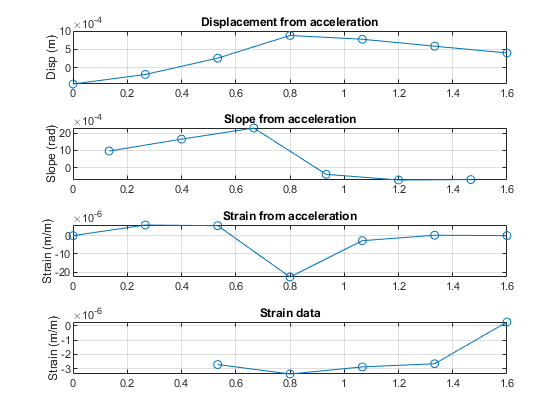

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Disp to Stress (differentiate in position and convert)
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% Distance from beam mid-line to surface
z = th/2;      %(m)

% Declare 
slope  = zeros(length(disp),(measPointsA-1)); %slope obtained from acc
strainA_z = zeros(size(disp));  %strain obtained from acc over z

% Differentiate with two point difference due to low spatial resolution
for i = 1:entries
    slope(i,1:6) = (diff(disp(i,:)))./dx;
    strainA_z(i,2:6) = (diff(slope(i,:)))./dx;
end

% Convert to strain and stress
strainA = strainA_z.*z;         %strain obtained from acc
stressA = strainA_z.*z.*E;      %stress obtained from acc

% Plot differentiation steps
frame = 109955;
xslope = linspace( (dx/2) ,(x(end)-dx/2) ,6);
tiledlayout(4,1)

% Displacement
nexttile
plot(x,disp(frame,:),'-o')
title('Displacement from acceleration')
grid on
ylabel('Disp (m)')

% Slope
nexttile
plot(xslope, slope(frame,:),'-o')
title('Slope from acceleration')
grid on
xlim([x(1) x(end)])
ylabel('Slope (rad)')

% Strain
nexttile
plot(x, strainA(frame,:),'-o')
title('Strain from acceleration')
grid on
ylabel('Strain (m/m)')

% Strain measurements (for verification)
nexttile
plot(x(3:7), strainData(frame,:),'-o')
title('Strain data')
grid on
ylabel('Strain (m/m)')
xlim([x(1) x(end)])

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Rainflow counting - Acc stress
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% Find measuring point with max stress
[MaxStressesA, MaxIndiciesA] = max(abs(stressA));
[MaxStressA, MaxStressLocationA] = max(MaxStressesA);
stressA4 = stressA(1:entries, MaxStressLocationA);
maxk(abs(stressA4),5)

ans = 	1.0e+08 *

    4.6439
    4.6439
    4.6438
    4.6438
    4.6437


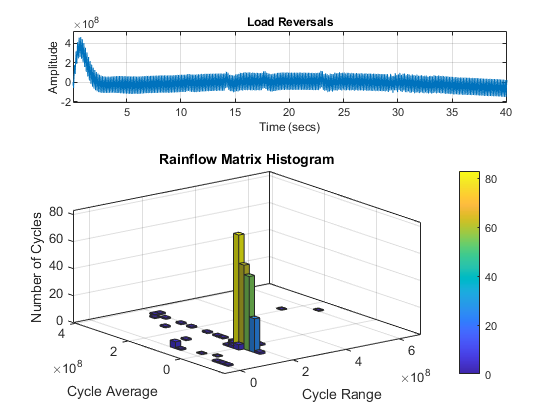


% Conduct rainflow count to obtain stress ranges and cycle counts
% Acceleration stress rainflow count plots:
rainflow(stressA4,t)

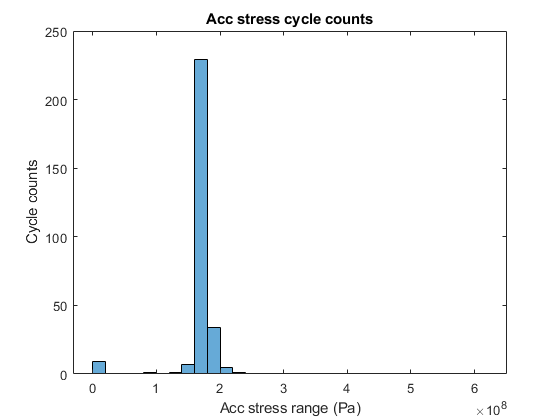

% Acceleration stress rainflow count data
[cA,histA,edgesA,rmmA,idxA] = rainflow(stressA4,t);

StressAccRainflowTable = array2table(cA,'VariableNames',{'Count','Range','Mean','Start','End'});
histogram('BinEdges',edgesA','BinCounts',sum(histA,2))
title('Acc stress cycle counts')
xlabel('Acc stress range (Pa)')
ylabel('Cycle counts')


% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Damage number -  Acc stress
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% Assign and declare vatiables
StressAccRanges = StressAccRainflowTable{:,'Range'}/1e6;  % Accelearation stress range (MPa)
StressAccCounts = StressAccRainflowTable{:,'Count'};  %Accelearation stress cycle counts
StressAccLives = zeros(length(StressAccRanges),1); %Number of cycles to failure at acceleration stress range

% Find acceleration stress life estimates
for i = 1:length(StressAccLives)
    if S(1) <= StressAccRanges(i)
        StressAccLives(i) = 1;
    elseif S(1) > StressAccRanges(i) && StressAccRanges(i) >= S(2)
        StressAccLives(i) = N1(StressAccRanges(i));
    elseif S(2) > StressAccRanges(i) && StressAccRanges(i) >= S(3)
        StressAccLives(i) = N2(StressAccRanges(i));
    elseif S(3) > StressAccRanges(i) && StressAccRanges(i) >= S(4)
        StressAccLives(i) = N3(StressAccRanges(i));
    elseif S(4) > StressAccRanges(i)
        StressAccLives(i) = inf;
    end
end

%Calculate damage of individual cyces
dd_StressAccDamages = StressAccCounts./StressAccLives;
% Calculate total damage of test run from acceleration
D_StressAccDamage = sum(dd_StressAccDamages)

D_StressAccDamage = 0.5000

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Rainflow counting - Strain stress
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% Find measuring point with max stress
[MaxStresses, MaxIndicies] = max(abs(stress));
[MaxStress, MaxStressLocation] = max(MaxStresses);
stress4 = stress(1:entries, MaxStressLocation);
maxk(abs(stress4),5)

ans = 	1.0e+07 *

    2.2810
    2.2810
    2.2808
    2.2805
    2.2805


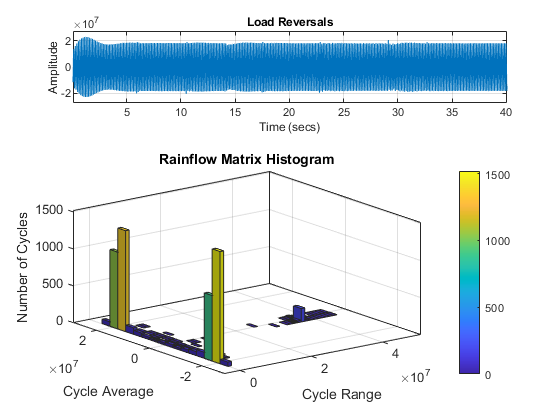


% Filter data
% Highpass filter at '0' Hz
N = 3;  % filter order
fc = 0.5; % cut off frequency (Hz)
[B,A] = butter(N,2*fc/fs,'high');

stress4filtered = filter(B,A,stress4);

% Band stop (notch) comb filter for 50 Hz and its products
% v = floor(fs/50);
v = 8;              %number of notch filters
a = zeros(1,v);
aa = zeros(1,v);

for i = 1:v
    a(i) = i*50 - 1;
    aa(i) = i*50 + 1.5;
    
    bsFilt(i) = designfilt('bandstopiir','FilterOrder',20, ...
         'HalfPowerFrequency1',a(i), ...
         'HalfPowerFrequency2',aa(i),...
         'SampleRate',fs);
    
    stress4filtered = filter(bsFilt(i),stress4filtered);
end

% bsFilt_low = designfilt('bandstopiir','FilterOrder',20, ...
%           'HalfPowerFrequency1',45, ...
%           'HalfPowerFrequency2',fs/2,...
%           'SampleRate',fs);
%      
% stress4filtered = filter(bsFilt_low,stress4filtered);

%fvtool(B,A,bsFilt(1),bsFilt(2),bsFilt(3),bsFilt(4),bsFilt(5))


% Conduct rainflow count to obtain stress ranges and cycle counts
rainflow(stress4filtered,t)

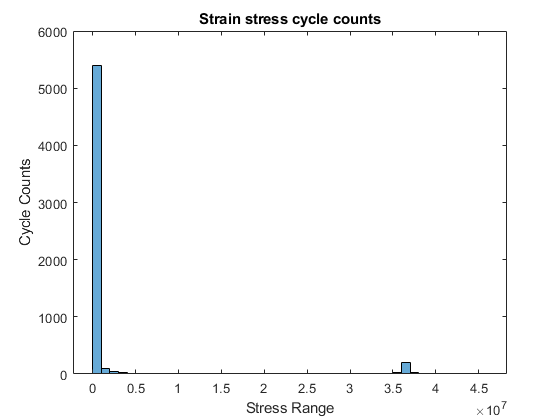


[c,hist,edges,rmm,idx] = rainflow(stress4filtered,t);

StressRainflowTable = array2table(c,'VariableNames',{'Count','Range','Mean','Start','End'});
histogram('BinEdges',edges','BinCounts',sum(hist,2))
title('Strain stress cycle counts')
xlabel('Stress Range')
ylabel('Cycle Counts')


% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Damage number - Strain stress
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% Assign and declare vatiables
StressRanges = StressRainflowTable{:,'Range'}/1e6;  % Stress range (MPa)
StressCounts = StressRainflowTable{:,'Count'};  % Stress cycle counts
StressLives = zeros(length(StressRanges),1); % Number of cycles to failure at stress range

% Find stress life estimates
for i = 1:length(StressLives)
    if S(1) <= StressRanges(i)
        StressLives(i) = 1;
    elseif S(1) > StressRanges(i) && StressRanges(i) >= S(2)
        StressLives(i) = N1(StressRanges(i));
    elseif S(2) > StressRanges(i) && StressRanges(i) >= S(3)
        StressLives(i) = N2(StressRanges(i));
    elseif S(3) > StressRanges(i) && StressRanges(i) >= S(4)
        StressLives(i) = N3(StressRanges(i));
    elseif S(4) > StressRanges(i)
        StressLives(i) = inf;
    end
end

%Calculate damage of individual cyces
dd_StressDamages = StressCounts./StressLives;
% Calculate total damage of test run from strain
D_StressDamage = sum(dd_StressDamages)

D_StressDamage = 0

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Tabulate and compare results
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
D_StressAccDamage

D_StressAccDamage = 0.5000

D_StressDamage

D_StressDamage = 0